### ROTATE AND RESZE METHODS ON COLOR,GRAY AND BINARY IMAGE

%Loading the Image
ci=imread('ROSE.jpg');

%Converting the Image
gi=rgb2gray(ci); %converting color to grey
bi=imbinarize(gi); %converting image to binary

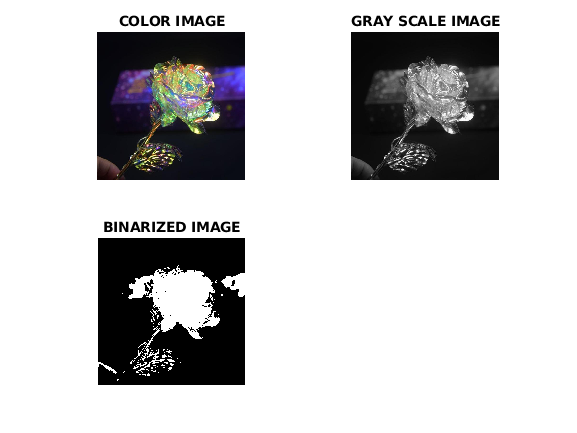

%Displaying the images 3 images on which I am working
clf;
subplot(2,2,1),imshow(ci), title('COLOR IMAGE');
subplot(2,2,2),imshow(gi), title('GRAY SCALE IMAGE');
subplot(2,2,3),imshow(bi), title('BINARIZED IMAGE');

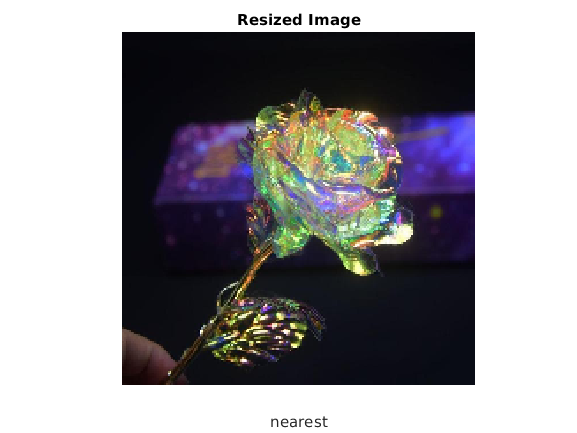

ans = 200×200×3 uint8 array
ans(:,:,1) =

     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     7     7     7     7     7     7     7     7     7     7     7     7     7     8     8     8     7     7     7     9     9     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     8     9     9     9     9     9     9     9     9     9     9     9     9     9    10    10    10    10    10     9    10    11     9     9     9    10    10     8     8     8     8     8    10    10    10     8     8     8     8     8     8     8     8     9     9     8     8     8     8     8     9     9     9     8     8     8    11    11    11    11    11    11    11    11    11    11    10     9    11    11    

%Resize the image
% Methods Used :- nearest, bilinear and bicubic 
%function rs is defined to resize the different images we call
rs(ci,200,200,"nearest")

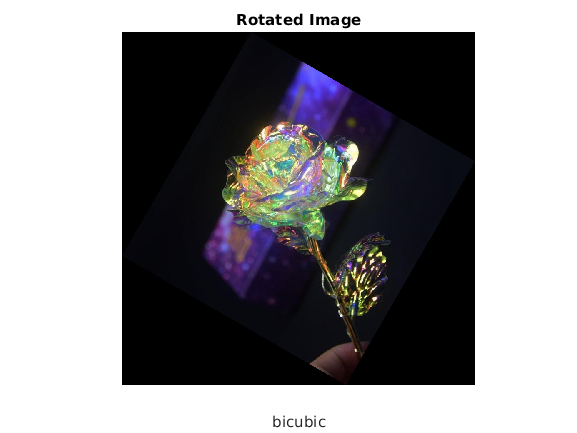

ans = 847×847×3 uint8 array
ans(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

% Rotation the image
% Methods Used :- nearest, bilinear and bicubic 
%function rot is defined to rotate the image
rot(ci,60,"bicubic")

function s=rot(x,y,z)
clf;
s=imrotate(x,y,z);
imshow(s);title("Rotated Image");xlabel('Method:');xlabel(z);
end

function i=rs(w,x,y,z)
clf;
i=imresize(w,[x,y],z);
imshow(i);title("Resized Image");xlabel('Method:');xlabel(z);
end
